# Surfaces defined explicitly by functions

If we assign the output of a function of two variables $f\left(x,y\right)$ to be a third variable, $z=f\left(x,y\right),$then the set of points in 3D define a surface. For example, $z = x^2 + y^2$ defines a paraboloid. This explicit surface can be visualized in MATLAB using a variety of techniques: we will focus here on using the **surf** function. First, we will define a domain using **meshgrid**

x = linspace(-2,2,100);
y = linspace(-2,2,100);
[X,Y]=meshgrid(x,y);

We now define a function that computes the z-coordinates corresponding to the paraboloid. You will find this function at the end of this script, and we copy it here for clarity

**function res = paraboloid(x,y)**

**    res = x.^2 + y.^2**

**end**

Notice that we use the **.^** operator since the input arguments to this function can and will be matrices. Now we can call this function and visualize the surface

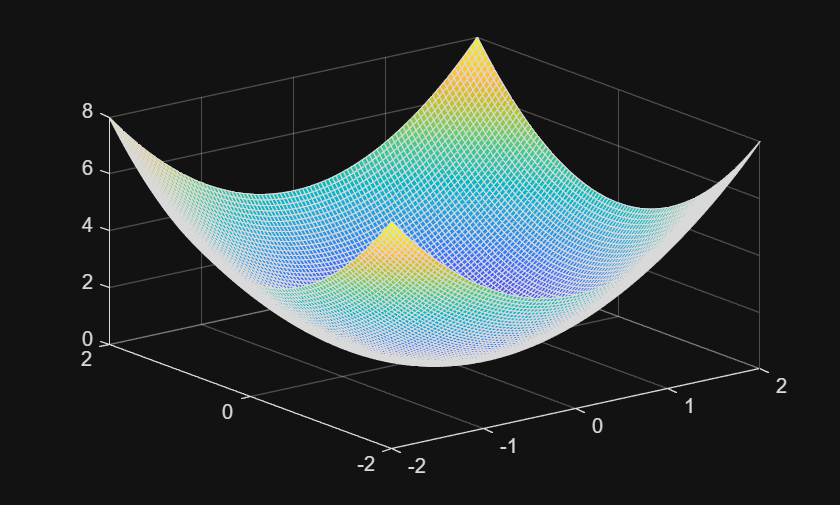

Z = paraboloid(X,Y);
surf(X,Y,Z)

**Exercise 1: **Use the **shading** function in Matlab to visualize this surface in three different ways (flat, faceted, interp)

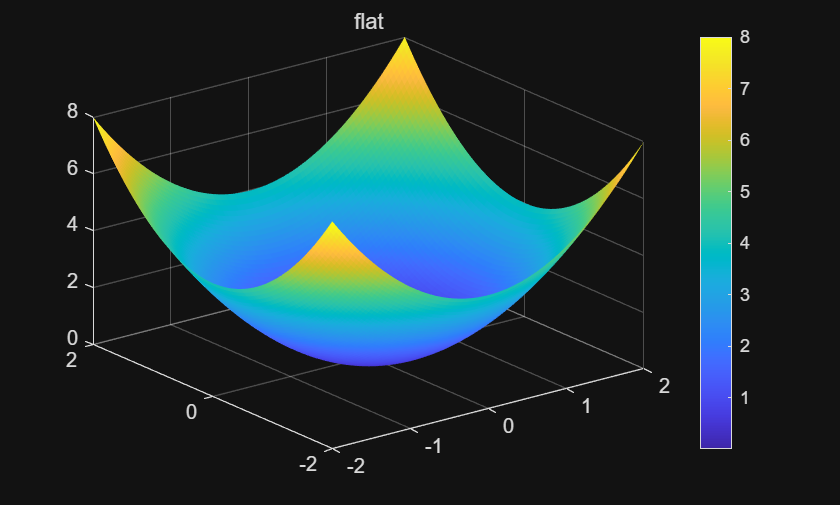



figure; surf(X,Y,Z); shading flat;    title('flat');    colorbar

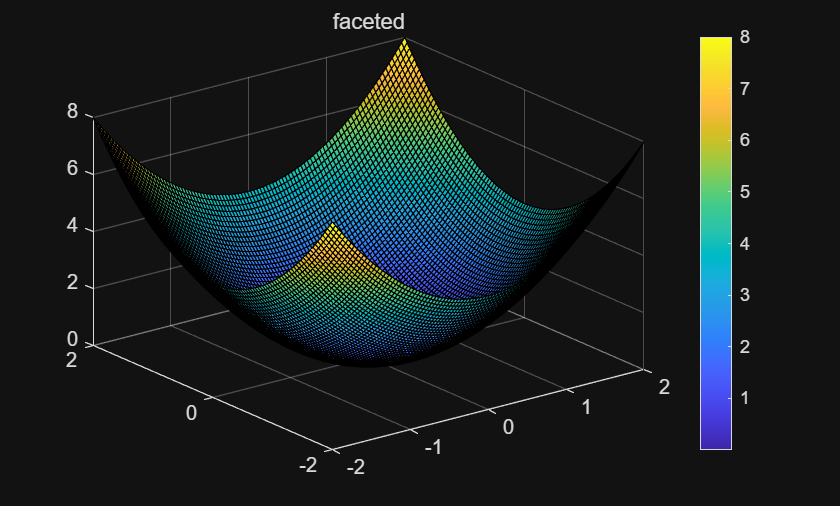

figure; surf(X,Y,Z); shading faceted; title('faceted'); colorbar

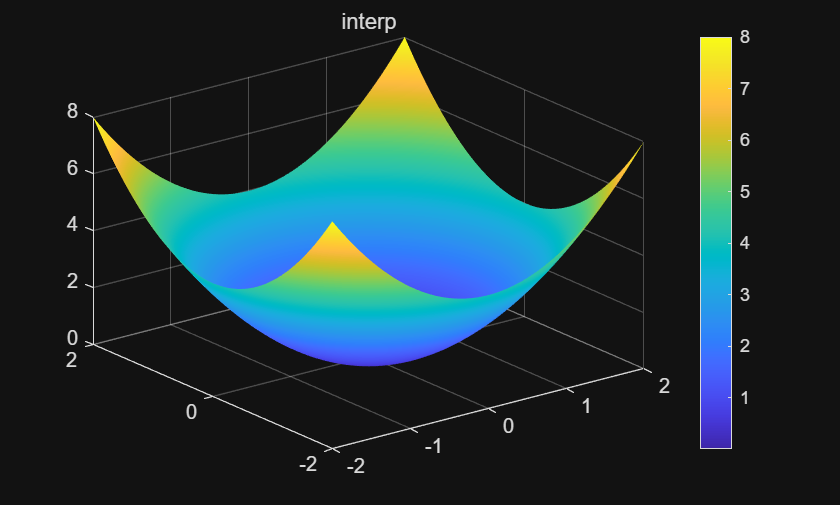

figure; surf(X,Y,Z); shading interp;  title('interp');  colorbar
colorbar



% shading INTERP
% shading faceted

## Contour plots

It is often helpful to visualize a surface by drawing the contours defined by holding z constant. For example, if we define z=1 in the equation for the paraboloid we obtain $x^2 + y^2 = 1$, which we know to be the equation of a circle of radius 1, centered at the origin. Choosing different values of z will define circles of radius $\sqrt{z}$.

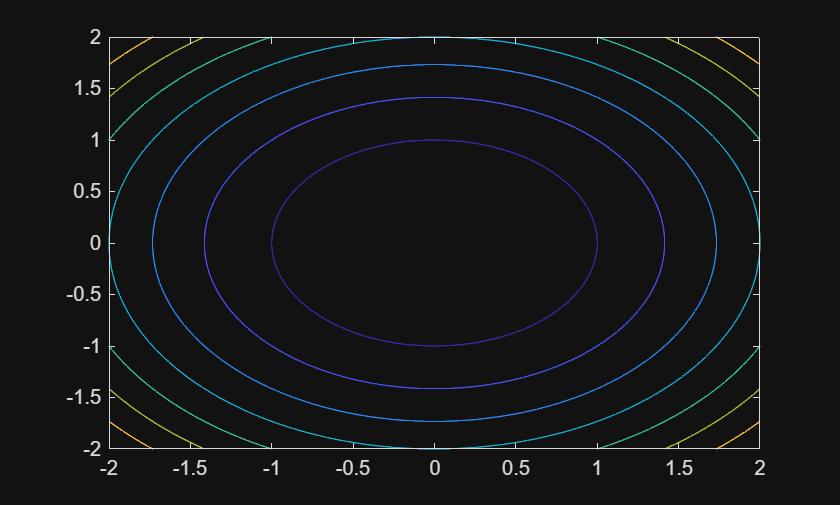

contour(X,Y,Z)

By default, **contour** will draw a set of contours that are chosen automatically by MATLAB. We can, of course, control the contours that are displayed by specifying them. The following example draws three contours corresponding to values of 1, 2, and 3.

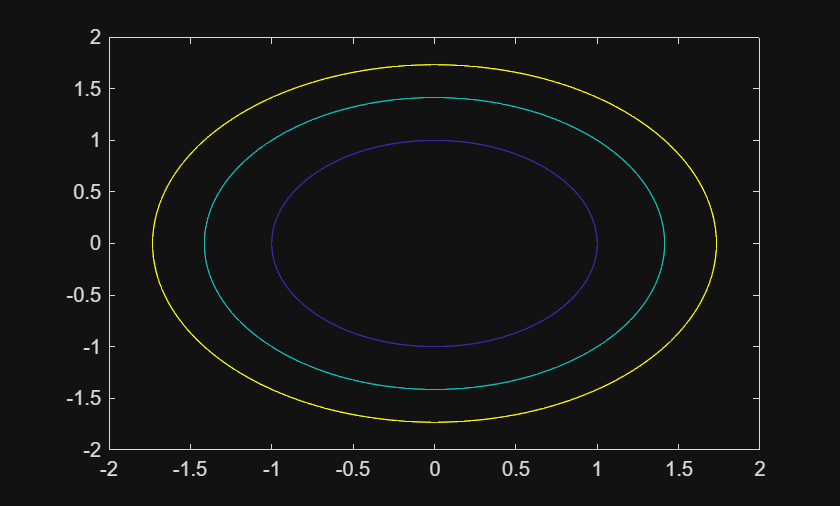

contour(X,Y,Z,[1,2,3])

 The results are circles of radius 1, $\sqrt{2}$, and $\sqrt{3}$ as you might have expected.

**Exercise 2: **Use the documentation for **contour** to figure out how to label each contour with the height.

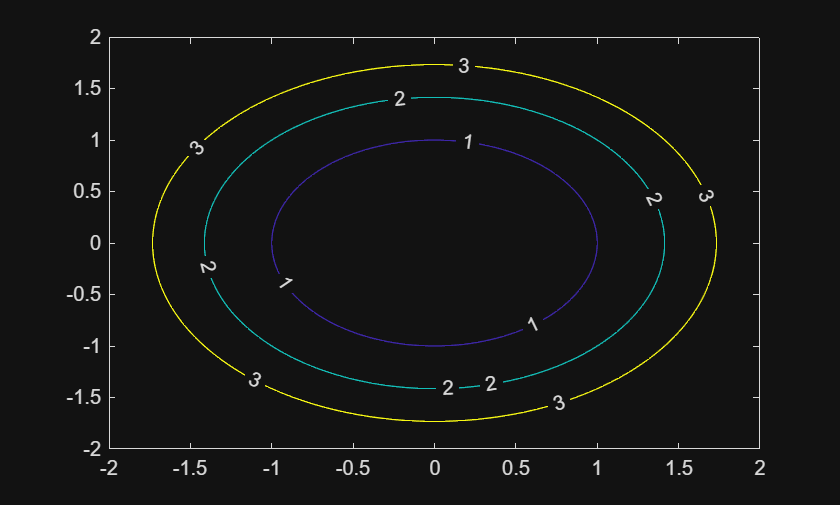

contour(X,Y,Z,[1,2,3],'showtext','on')

**Exercise 3:** Consider the surface defined by $z = c \left( \frac{x^2}{a^2} + \frac{y^2}{b^2} \right)$. 

- Write a function that accepts x, y, a, b,and c as input, and returns the value of z as output. 

- Visualize the surface (using **surf** and **contour**) for different values of a, b, and c. 

- What features of the surface do a, b, and c control?

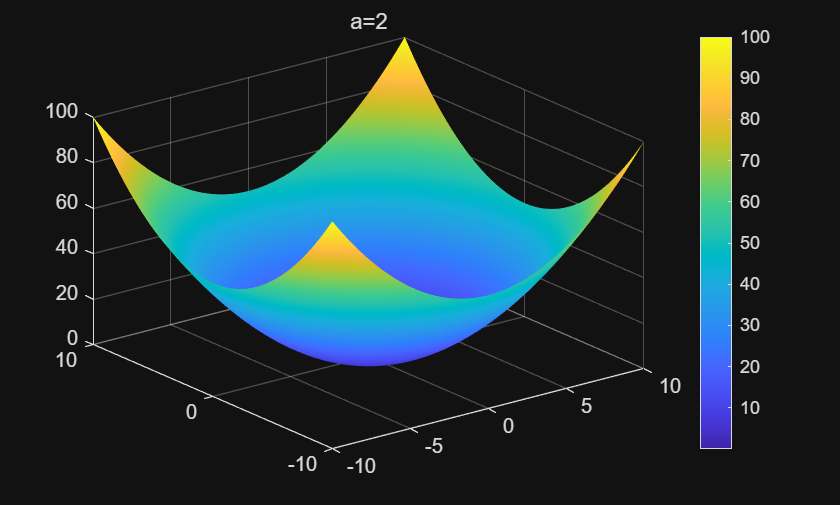

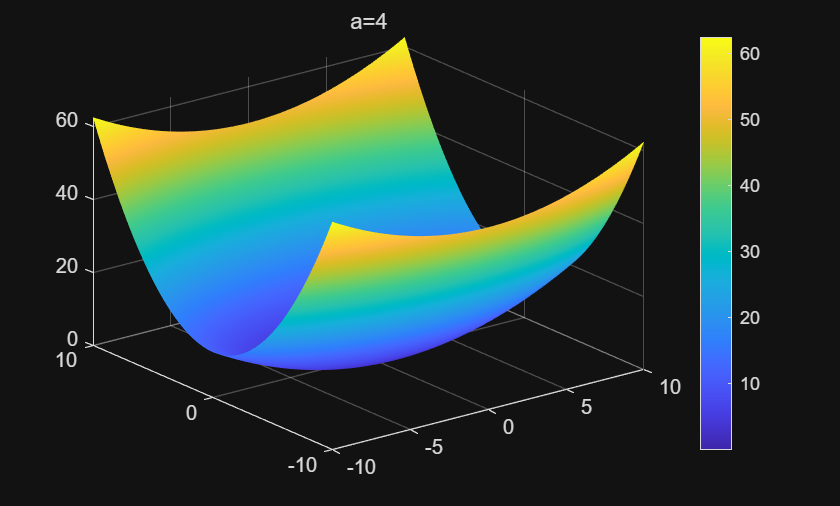

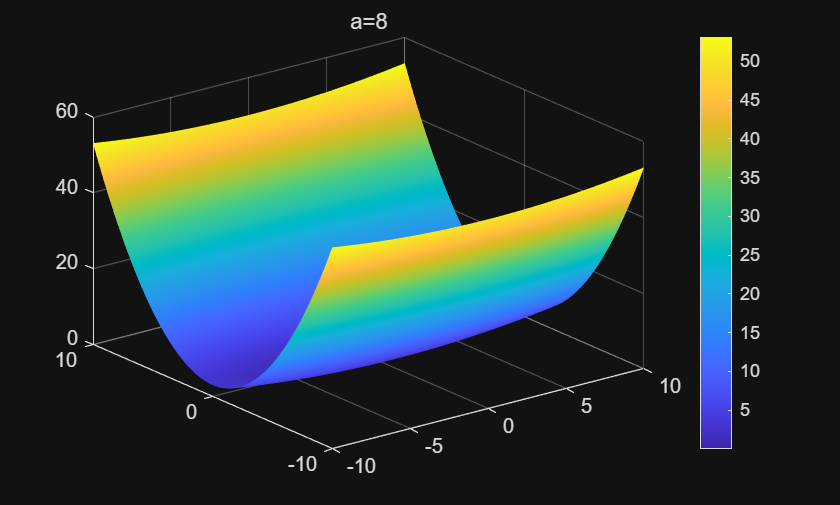

x = linspace(-10,10,1000);
y = x;
[xgrid ygrid] = meshgrid(x,y);
alpha = [2,4,8];
beta = [2,4,8];
cigma = [-2,2];
[X,Y]=meshgrid(x,y);
for a = alpha
    Z = e3(a,2,2,X,Y);
    figure; surf(X,Y,Z); shading flat;    title('a='+string(a));    colorbar
    %contour (xgrid,ygrid,e3(a,b,c,xgrid,ygrid),'showtext',['on'])
end

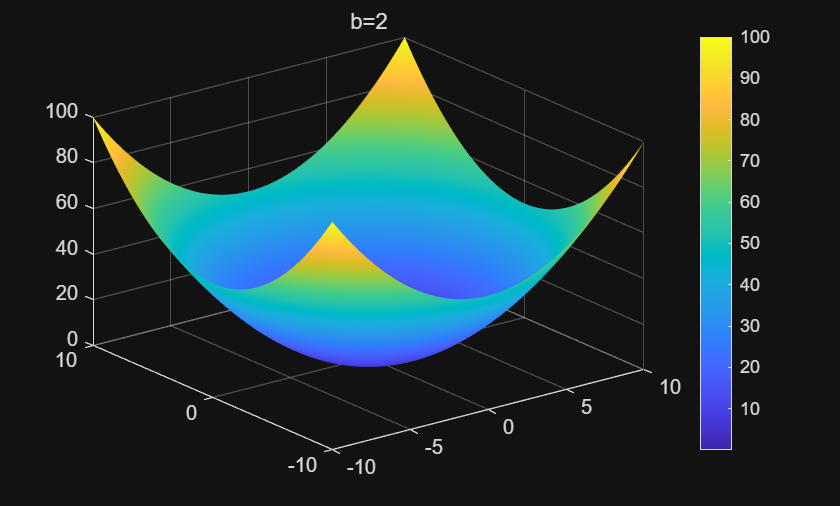

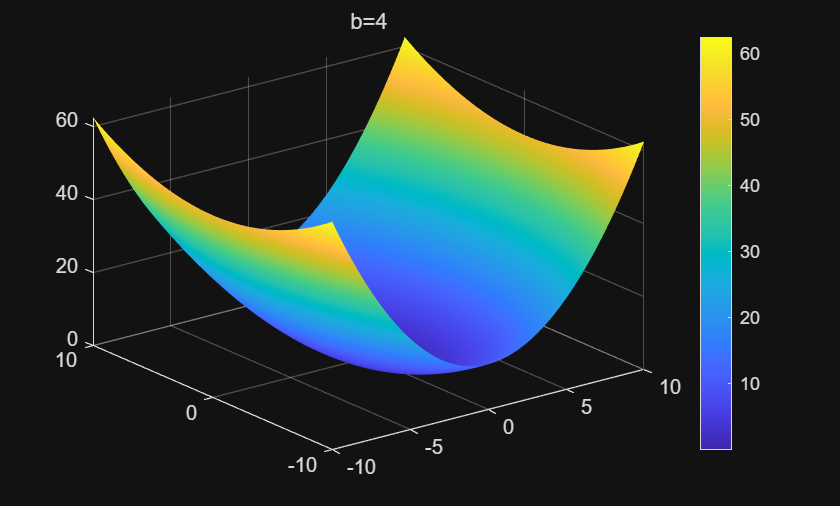

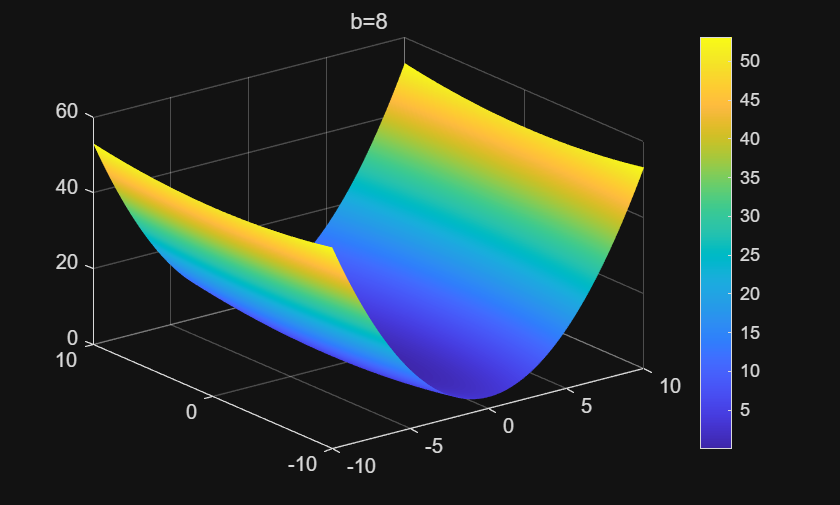

for b = beta
    Z = e3(2,b,2,X,Y);
    figure; surf(X,Y,Z); shading flat;    title('b='+string(b));    colorbar
end

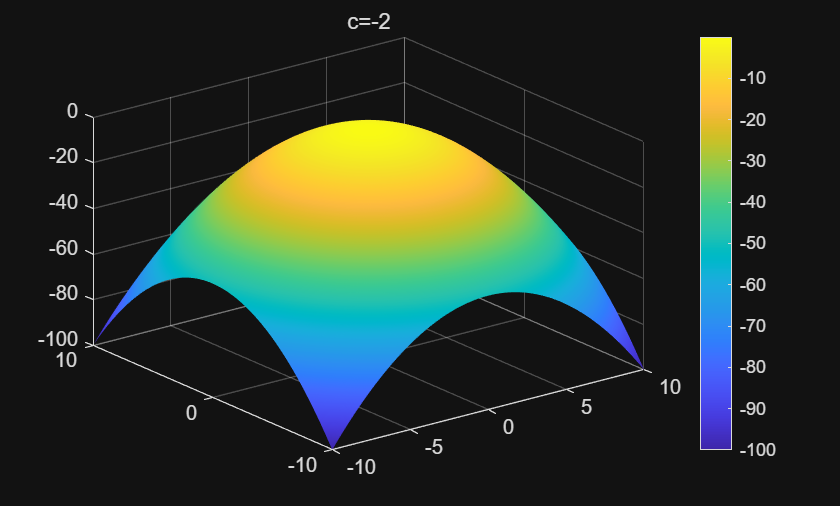

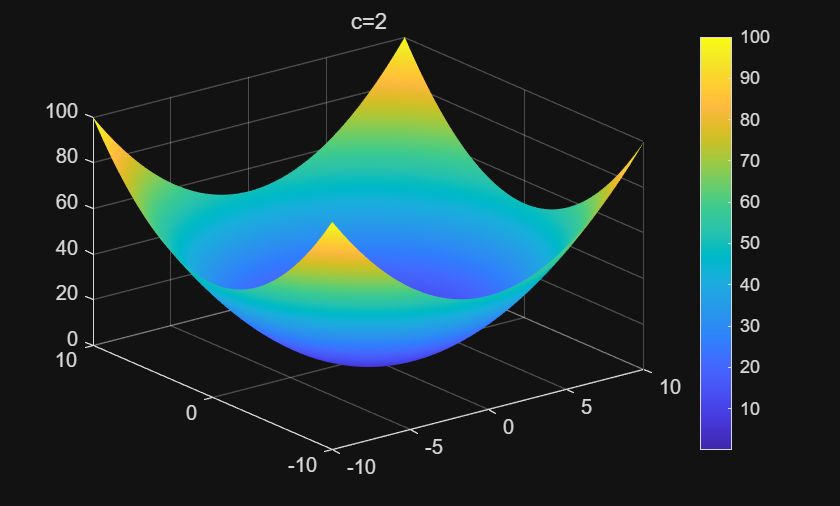

for c = cigma
    Z = e3(2,2,c,X,Y);
    figure; surf(X,Y,Z); shading flat;    title('c='+string(c));    colorbar
end

function res = paraboloid2 (a,b,c,x,y)

res = c*(x.^2./a^2 + y.^2./b^2);
end


## Function definitions

function res = paraboloid(x,y)
    res = x.^2 + y.^2;
end
function res = e3(a,b,c,x,y)
    res = c*(x.^2./a^2 + y.^2./b^2);
end
